# multistep_20260923_214220

data = multistep_20260923_213949;
%data = multistep_20260923_214220;


%
%

data.sample_time_us = data.sample_time_us(:,1)/1000000;
data = renamevars(data, "sample_time_us", "time");
data = renamevars(data, "pwm_applied_percent", "pwm");
data = renamevars(data, "current_mean_a", "currentMEAN");
data = renamevars(data, "output_position_rad", "rad");
data = renamevars(data, "output_speed_rad_s", "rads");

%Tiempo de muestreo
Ts = data.time(2,1) - data.time(1,1);
%Entrada al sistema PWM
u = data.pwm;
u1 = data.rad;
u2 = data.rads;
%Salida del sistema
y = data.currentMEAN;

 
% Crear los datos de identificación para la respuesta de corriente
datCurrent = iddata(y, u, Ts);
datRads    = iddata(u2, y, Ts);
datRad     = iddata(u1, u2, Ts);

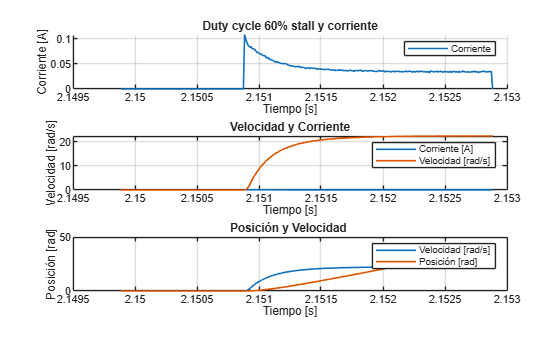


figure

subplot(3,1,1)
%plot(data.time, u, 'LineWidth', 1.2)
hold on
plot(data.time/1000, y, 'LineWidth', 1.2)
grid on
xlabel('Tiempo [s]')
ylabel('Corriente [A]')
title('Duty cycle 60% stall y corriente')
%title('Duty cycle 60% noload y corriente')
legend('Corriente')

subplot(3,1,2)
plot(data.time/1000, y, 'LineWidth', 1.2)
hold on
plot(data.time/1000, u2, 'LineWidth', 1.2)
grid on
xlabel('Tiempo [s]')
ylabel('Velocidad [rad/s]')
title('Velocidad y Corriente')
legend('Corriente [A]', 'Velocidad [rad/s]')

subplot(3,1,3)
plot(data.time/1000, u2, 'LineWidth', 1.2)
hold on
plot(data.time/1000, u1, 'LineWidth', 1.2)
grid on
xlabel('Tiempo [s]')
ylabel('Posición [rad]')
title('Posición y Velocidad ')
legend('Velocidad [rad/s]', 'Posición [rad]')

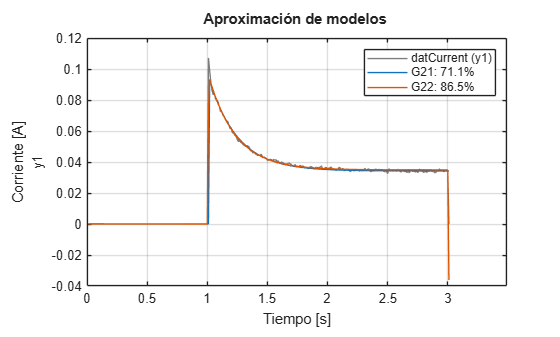


% Identificar un modelo de corriente a partir de los datos registrados

G10 = tfest(datCurrent,1,0);   % 1 polo
G20 = tfest(datCurrent,2,0);   % 2 polos
G21 = tfest(datCurrent,2,1);   % 2 polos + 1 cero
G22 = tfest(datCurrent,2,2);   % 2 polos + 2 cero

figure
compare(datCurrent,G21,G22)
xlabel('Tiempo [s]')
ylabel('Corriente [A]')
title('Aproximación de modelos ')
grid on

G22


G22 =
 
  From input "u1" to output "y1":
  0.001184 s^2 + 1.441 s + 2.325
  ------------------------------
       s^2 + 904.4 s + 3996
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 2
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using TFEST on time domain data "datCurrent".
Fit to estimation data: 86.51%                         
FPE: 9.712e-06, MSE: 9.27e-06                          
 
Model Properties


#### MODELO CORRIENTE Y CONTROL DE CORRIENTE.

s = tf('s');
Best_model =  (0.001795*s^2 + 0.04793*s + 0.1065)/(s^2 + 26.46*s + 58.99); % stall  60%
Best_model_1 =  (0.001184*s^2 + 1.441*s + 2.325)/(s^2 + 904.4*s + 3996);   % no load  60%
Current_controller_stall = (1.718*s+6343)/s;
Current_controller_noload =  (8.832*s + 8.009e04)/s


Current_controller_noload =
 
  8.832 s + 80090
  ---------------
         s
 
Continuous-time transfer function.


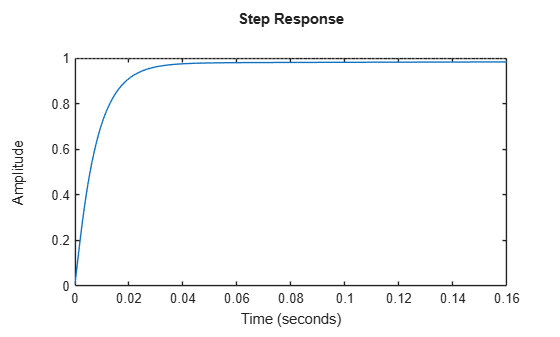

figure 
step(feedback(Current_controller_noload*Best_model_1,1))

#### IDENTIFICACION DE CORRIENTE PRUEBAS DEL 60% EN STALL Y NO LOAD

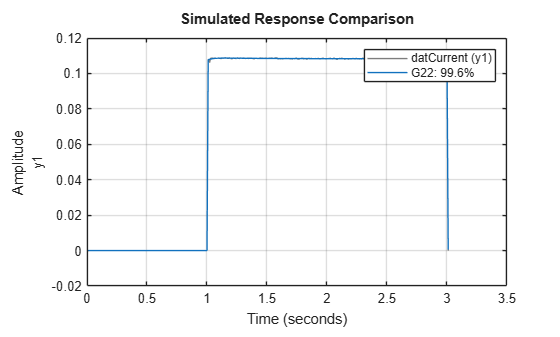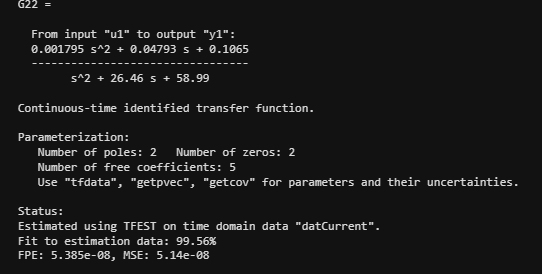

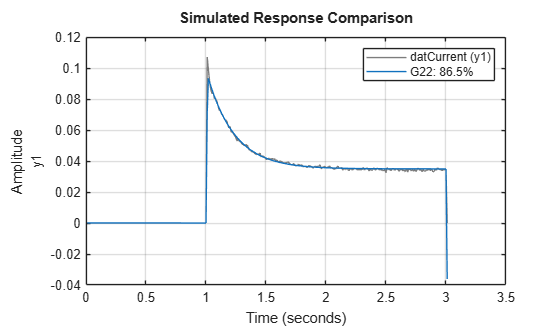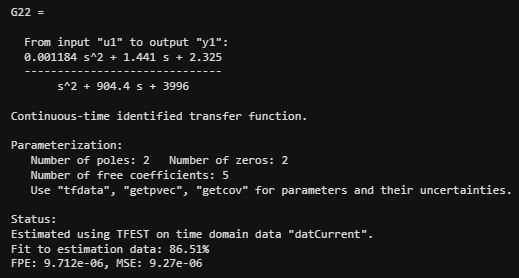

#### MODELO VELOCIDAD Y CONTROL DE VELOCIDAD.

% Identificar un modelo de velocidad a partir de los datos registrados

G10 = tfest(datRads,1,0);   % 1 polo
G20 = tfest(datRads,2,0);   % 2 polos
G21 = tfest(datRads,2,1);   % 2 polos + 1 cero
G22 = tfest(datRads,2,2);   % 2 polos + 2 cero

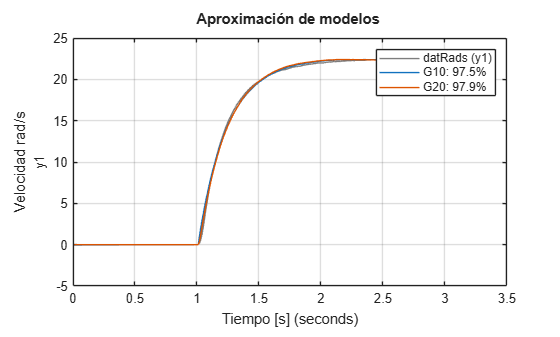

figure
compare(datRads,G10,G20)
xlabel('Tiempo [s]')
ylabel('Velocidad rad/s')
title('Aproximación de modelos ')
grid on

G20


G20 =
 
  From input "u1" to output "y1":
        1.107e05
  ---------------------
  s^2 + 110.1 s + 172.3
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "datRads".
Fit to estimation data: 97.92%                      
FPE: 0.04603, MSE: 0.04452                          
 
Model Properties


best_model_rads = (1.107e05)/(s^2 + 110.1*s + 172.3);
rads_controller =  (0.0284*s + 0.01392)/s


rads_controller =
 
  0.0284 s + 0.01392
  ------------------
          s
 
Continuous-time transfer function.


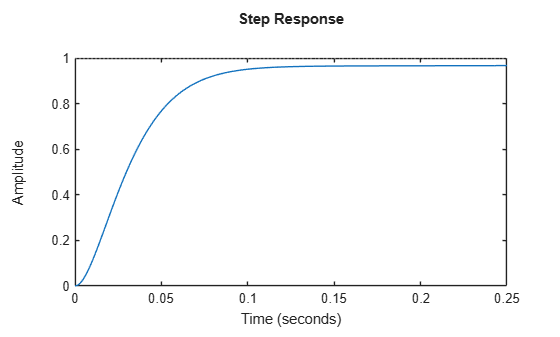

figure 
step(feedback(rads_controller*best_model_rads,1))

#### MODELO POSICION Y CONTROL DE POSICION.

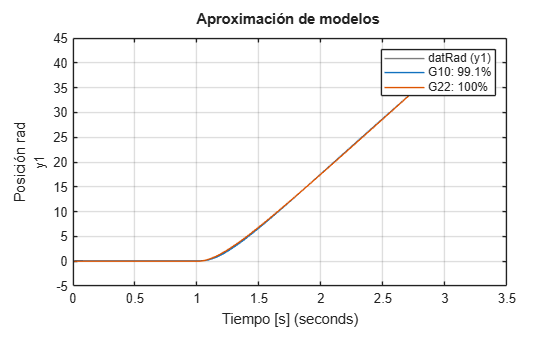

% Identificar un modelo de velocidad a partir de los datos registrados

G10 = tfest(datRad,1,0);   % 1 polo
G20 = tfest(datRad,2,0);   % 2 polos
G21 = tfest(datRad,2,1);   % 2 polos + 1 cero
G22 = tfest(datRad,2,2);   % 2 polos + 2 cero

figure
compare(datRad,G10,G22)
xlabel('Tiempo [s]')
ylabel('Posición rad')
title('Aproximación de modelos ')
grid on

best_model_rad = (0.04939*s^2 + 10.5*s + 317)/(s^2 + 317*s + 0.01188)


best_model_rad =
 
  0.04939 s^2 + 10.5 s + 317
  --------------------------
    s^2 + 317 s + 0.01188
 
Continuous-time transfer function.


rad_controller =      (6.166*s + 3192)/s


rad_controller =
 
  6.166 s + 3192
  --------------
        s
 
Continuous-time transfer function.


#### EVALUACION DE CONTROLADORES

s = tf('s');
%CORRIENTE
%G = Best_model_1;
%C = Current_controller_noload;
%VELOCIDAD
%G = (1.107e05)/(s^2 + 110.1*s + 172.3);
%C = (0.0284*s + 0.01392)/s;
%POSICION
G = (0.04939*s^2 + 10.5*s + 317)/(s^2 + 317*s + 0.01188);
C = (6.166*s + 3192)/s;
T = feedback(C*G,1);
stepinfo(T)

ans = struct with fields:
         RiseTime: 0.0170
    TransientTime: 0.1034
     SettlingTime: 0.0998
      SettlingMin: 0.9139
      SettlingMax: 1.1354
        Overshoot: 13.5364
       Undershoot: 0
             Peak: 1.1354
         PeakTime: 0.0453


ess = abs(1 - 0.996)*100

ess = 0.4000

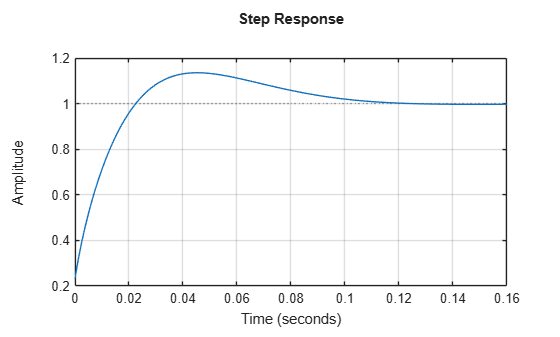

step(T)
grid on